# Part 1: Isolation time

Analyses of Experiment 1. 

## A) Specify conditions

 exp_ind = find(strcmp(rdb.experiment, 'org'));
 
[u_paircodes, ia_pairs, ic_pairs] = unique(rdb.paircode(exp_ind));
 condvec = [1 2 3]; % 1 min 45 min 1 day
 phystypes = [-1 1 2 3];
 betypes = phystypes; %oops. Used phystypes a few places. But I meant betypes. Now they'll be the same. ]]></w:t></w:r></w:p><w:p><w:pPr><w:sectPr/></w:pPr></w:p><w:p><mc:AlternateContent xmlns:mc="http://schemas.openxmlformats.org/markup-compatibility/2006"><mc:Choice Requires="R2018b"><w:pPr><w:pStyle w:val="heading2"/><w:jc w:val="left"/></w:pPr></mc:Choice><mc:Fallback><w:pPr><w:pStyle w:val="heading"/><w:jc w:val="left"/></w:pPr></mc:Fallback></mc:AlternateContent><w:bookmarkStart w:name="MW_H_3B86E0E3" w:id="H_3B86E0E3"/><w:r><w:t>1.1 Physical interactions protocol</w:t></w:r><w:bookmarkEnd w:id="H_3B86E0E3"/></w:p><w:p><w:pPr><w:pStyle w:val="text"/><w:jc w:val="left"/></w:pPr><w:r><w:t></w:t></w:r></w:p><w:p><w:pPr><w:pStyle w:val="code"/></w:pPr><w:r><w:t><![CDATA[%open Desktop\Degu\reunion\Lidhar_ReunionMotivation_Figure1.pptx]]></w:t></w:r></w:p><w:p><w:pPr><w:sectPr/></w:pPr></w:p><w:p><mc:AlternateContent xmlns:mc="http://schemas.openxmlformats.org/markup-compatibility/2006"><mc:Choice Requires="R2018b"><w:pPr><w:pStyle w:val="heading2"/><w:jc w:val="left"/></w:pPr></mc:Choice><mc:Fallback><w:pPr><w:pStyle w:val="heading"/><w:jc w:val="left"/></w:pPr></mc:Fallback></mc:AlternateContent><w:bookmarkStart w:name="MW_H_F38EEFDC" w:id="H_F38EEFDC"/><w:r><w:t>1.2 Physical interactions: combined</w:t></w:r><w:bookmarkEnd w:id="H_F38EEFDC"/></w:p><w:p><w:pPr><w:pStyle w:val="code"/></w:pPr><w:r><w:t><![CDATA[% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1.1 Total physical interaction data


## B. Physical interactions 

### B.1 Summed behavior analyses

Create the physical behavior matrix

septime_mat = nan(length(u_paircodes),length(condvec),length(phystypes));
 for i = 1:length(u_paircodes)
    for j = 1:length(condvec)
         curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(j)), exp_ind);
         cofind{j}(i) = curind;
         septime_mat(i,j,1:length(phystypes)) = sum(rdb.sumbehav(curind,:),1);
    end
 end

 scofind = i;


Figure of total physical interaction data

 stm_all = nansum(septime_mat,3);
% not normalized:
 figure
 f2A = subplot(1,5,1:3);
 bar(1:3, nanmean(stm_all), 'FaceColor', 'k');
 hold

Current plot held


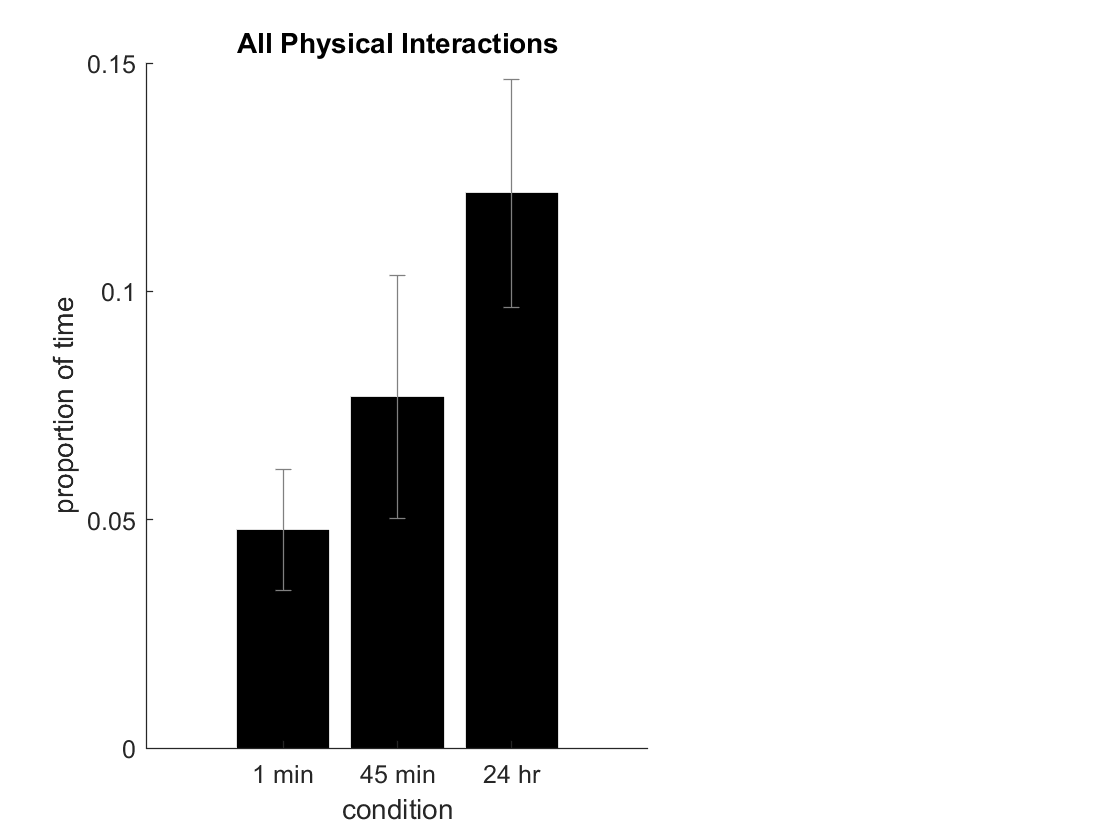

 eb = errorbar(1:3, nanmean(stm_all), nanstd(stm_all)/sqrt(size(septime_mat,1)-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
 set(f2A, 'XTickLabel', {'1 min', '45 min', '24 hr'});
 set(get(f2A, 'XLabel'), 'String', 'condition');
 set(get(f2A, 'YLabel'), 'String', 'proportion of time');
 set(get(f2A, 'Title'), 'String', 'All Physical Interactions');
 box off

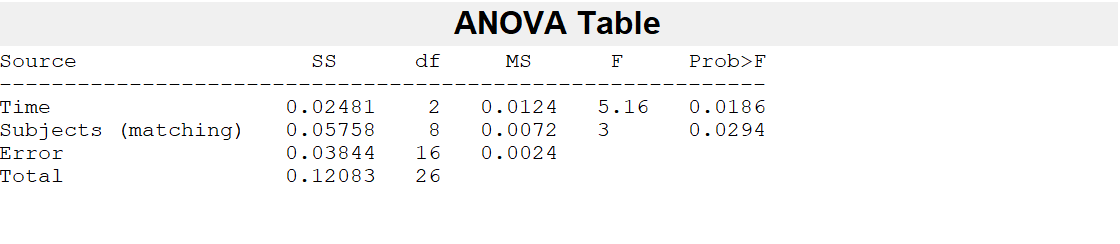

 [p, table] = anova_rm(stm_all);

 [a, b, ~, d] = ttest(stm_all(:,1)-stm_all(:,3))

a = 1

b = 0.0245

d = struct with fields:
    tstat: -2.7637
       df: 8
       sd: 0.0800


 
 cd = mean(stm_all(:,1)-stm_all(:,3))/std(stm_all(:,1)-stm_all(:,3))

cd = -0.9212

 stm_all_iso = stm_all;

### B.2 Physical interaction types

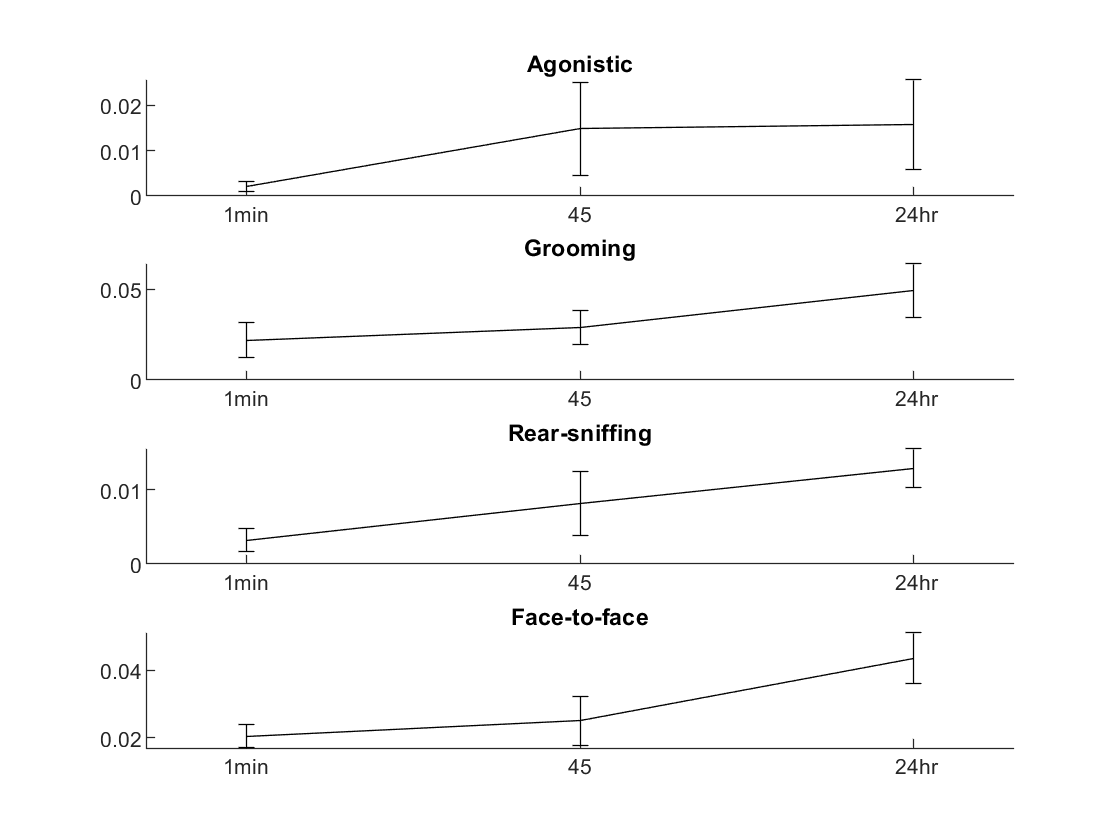


% %%%%%
 behaviortypes = {'Agonistic' 'Grooming' 'Rear-sniffing' 'Face-to-face'};
%  
%  f2B = subplot(1,5,4:5);
%  isc = imagesc(squeeze(nanmean(septime_mat,1))');
%  set(f2B, 'XTickLabel', {'1 min', '45', '24 hr'});
%  colormap(f2B, 'gray');
% set(f2B, 'YTick', [1 2 3 4])
% set(f2B, 'YTickLabel', {'A' 'G' 'RS' 'FF'})
% colorbar(f2B)
%  
% %%%%%%%%%
% Alternative B: more bar graphs

figure
 for i = 1:4
%     f2B = subplot(4,3,i*3);
    f2B = subplot(4,1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septime_mat(:,:,i)), nanstd(septime_mat(:,:,i))/sqrt(size(septime_mat,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', {'1min', '45', ' 24hr'});
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

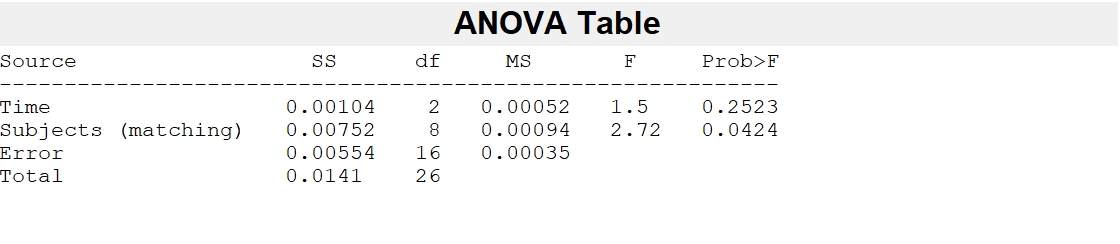

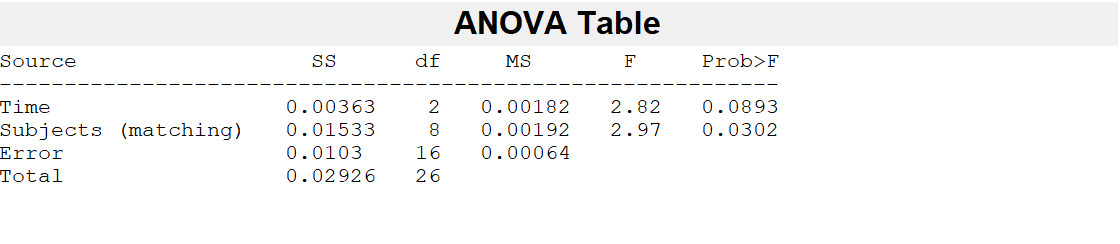

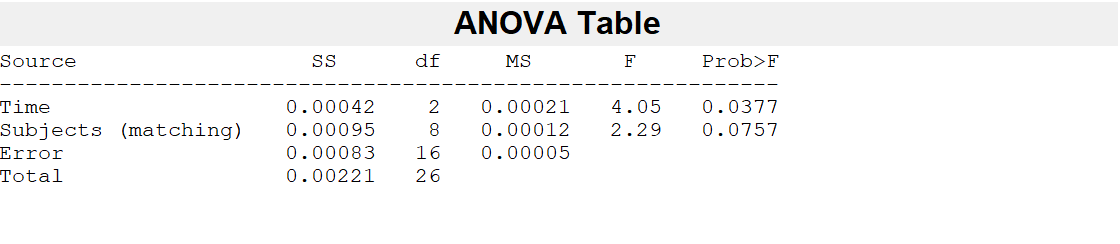

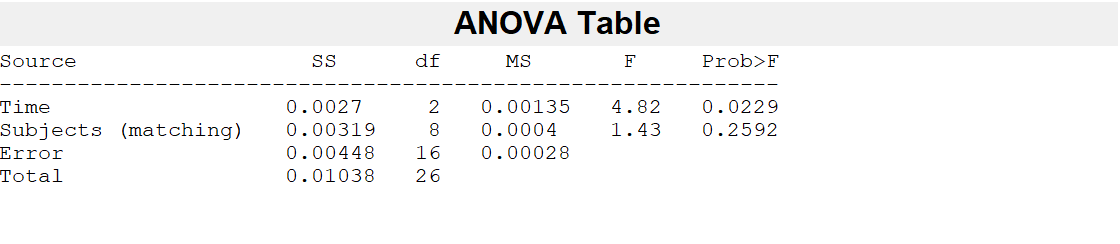

 for i = 1:4
     [psub(i,:) j] = anova_rm(septime_mat(:,:,i));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
 end

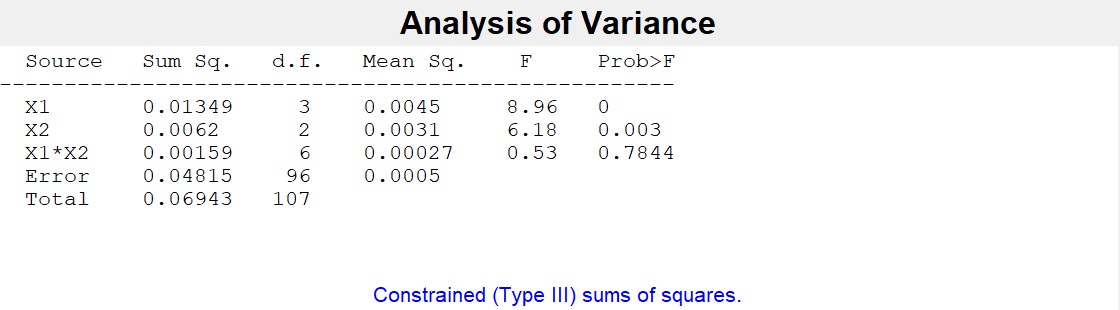

% 2-Way ANOVA 
 s = septime_mat;
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');

### B.3 Temporal distribution of interactions over time

a.Cumulative activity

 cumsum_f_a_d1 = nan(length(u_paircodes), 601, length(condvec));
h_cs_f_a = nan(length(u_paircodes), length(condvec));
 
 for k = 1:length(condvec)
    for i = 1:length(u_paircodes)
        
        curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(k)), exp_ind);
  
        cumsum_f_a_d1(i,:,k) = cumsumbehav(curind,:);
        h_cs_f_a(i,k) = cumsumbehav_ht(curind);                
    end
 end
 
 

 Display cumsums

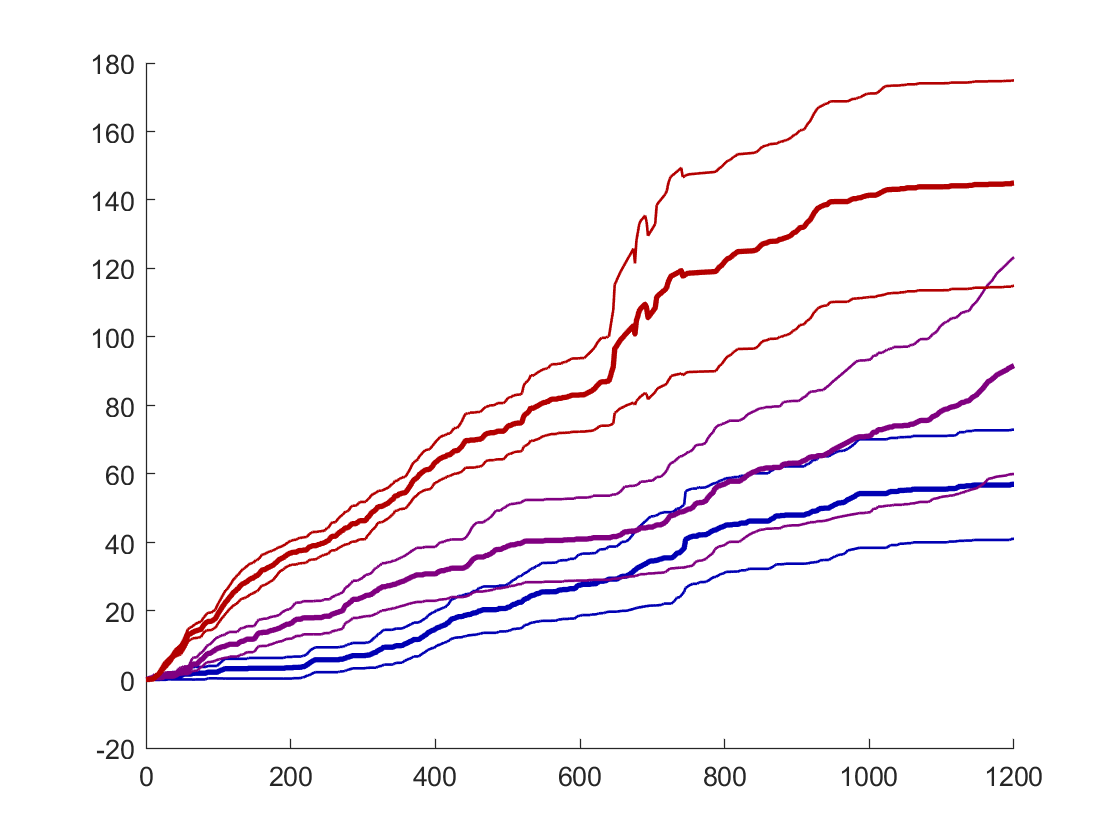

% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'k:');
% hold on
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'k--');
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'k-');
% 


figure
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'Color', [0 0 .7]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'Color', [.5 0 .5]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'Color', [.7 0 0]);

box off

clear a b 
for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,1)-cumsum_f_a_d1(:,i,2));
 end
 [min_1_45 locmin_1_45] = min(b)

min_1_45 = 0.0014

locmin_1_45 = 112

 [h, p, ci, stats] = ttest(cumsum_f_a_d1(:,locmin_1_45, 1) - cumsum_f_a_d1(:,locmin_1_45,2));
 stats

stats = struct with fields:
    tstat: -4.7876
       df: 8
       sd: 8.6724


 
  for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,1)-cumsum_f_a_d1(:,i,3));
  end
  [min_1_24 locmin_1_24] = min(b)

min_1_24 = 6.8149e-06

locmin_1_24 = 97

 [h, p, ci, stats] = ttest(cumsum_f_a_d1(:,locmin_1_24, 1) - cumsum_f_a_d1(:,locmin_1_24,3));
 stats

stats = struct with fields:
    tstat: -10.2979
       df: 8
       sd: 9.5050


 
 
 
    for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,2)-cumsum_f_a_d1(:,i,3));
    end
    [min_45_24 locmin_45_24] = min(b)

min_45_24 = 1.2582e-05

locmin_45_24 = 141

     [h, p, ci, stats] = ttest(cumsum_f_a_d1(:,locmin_45_24, 2) - cumsum_f_a_d1(:,locmin_45_24,3));
 stats

Latency to first interaction: compute the matrix for this experiment

latmat_f = nan(length(u_paircodes), length(phystypes), length(condvec));
latmat5_f = nan(length(u_paircodes), length(phystypes), length(condvec));
 for i = 1:length(u_paircodes)
     for k = 1:length(condvec)
         curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(k)), exp_ind);
         latmat_f(i,:, k) = be_lat(curind,:);    
         latmat5_f(i,:,k) = be_lat5(curind,:);
     end
 end

Display latencies, collective

 f = figure
lm = min(latmat_f, [], 2);
bar(nanmean(squeeze(lm)), 'k')
hold on
errorbar(1:3, nanmean(squeeze(lm)), nanstd(squeeze(lm))/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
box off
set(get(f, 'Children'), 'XTick', [1:3])
set(get(f, 'Children'), 'XTickLabel', {'1 min' '45 min' '24 hr'});
p = anova_rm(squeeze(lm));

Display the latencies across types

titlecell = {'agonistic', 'body sniffing', 'rear sniffing', 'face-to-face'};

 figure
 
 for i = 1:length(betypes)
    d = subplot(length(betypes),1,i);
    
    errorbar(1:length(condvec), nanmean(squeeze(latmat_f(:, i,:))), nanstd(squeeze(latmat5_f(:,i,:)))/sqrt(8), 'k');
%    hold  on
   set(d, 'XLim', [.75 3.25]);
   set(d, 'XTick', [1:3])
   if i < 4
       set(d, 'XTickLabel', {'' '' '' });
   else
       set(d, 'XTickLabel', {'1 min' '45 min' '24 hr'});
   end
   title(titlecell{i});
    box off
 end

Stats on latencies

for i = 1:4
     [psub(i,:) j] = anova_rm(squeeze(latmat_f(:,i,:)));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
end


### B.5 Temporal relationships between behavior types

Not used: transition matrix by session

%[transmatcell transmatsig tsig] = reunion_transmat(rdb);

condvec = [1:3];
colorcodes = [.5 .5 .5; 0 0 .5; 1 0 0 ];

figure
i = 1;
curind = find(ismember(rdb.condition(:,1), condvec));
%for i = 1:length(condvec)
    for j = 1:16
        subplot(4,4,j);
        
%        curind = find(rdb.condition(:,1) == condvec(i));
        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,curind))'), nanstd(squeeze(be_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', colorcodes(2,:))  ;  
        hold on
        errorbar_alt(xaxis, nanmean(squeeze(SH_xcorr(j,:,curind))'), nanstd(squeeze(SH_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', colorcodes(1,:))  ; 
        box off
    end    
    

    stats 


curind = find(ismember(rdb.condition(:,1), condvec));
mxc = nan(size(be_xcorr,1), 2, size(be_xcorr,3));

mxc(:,1,:) = nanmean(be_xcorr(:,1:19,:),2);
mxc(:,2,:) = nanmean(be_xcorr(:,23:42,:),2);

sxc(:,1,:) = nanmean(SH_xcorr(:,1:19,:),2);
sxc(:,2,:) = nanmean(SH_xcorr(:,23:42,:),2);

curind = find(ismember(rdb.condition(:,1), condvec));

% for a while the below wasn't working because "b1" (and others) had been
% assigned to serve as handles to a deleted bar in a plot. If this happens,
% clear b1, bb1, etc.
clear b1 bb1 a1 aa1 c1 d1 cc1 dd1
for i = 1:16
    [a1(i), b1(i), ~, d1(i)] = ttest(squeeze(mxc(i,1,curind))-1);
    [aa1(i), bb1(i), ~, dd1(i)] = ttest(squeeze(mxc(i,1,curind)-sxc(i,1,curind)));
end
clear b2 bb2 a2 aa2 c2 d2 cc2 dd2

for i = 1:16
    [a2(i), b2(i), ~, d2(i)] = ttest(mxc(i,2,curind)-1);
    [aa2(i), bb2(i), ~, dd2(i)] = ttest(mxc(i,2,curind)-sxc(i,2,curind));
end

[codes(:,1:2,1) b1' bb1' b2' bb2' [d1(:).tstat]' [dd1(:).tstat]' [d2(:).tstat]' [dd2(:).tstat]']

Significant relationships:

- Body sniffing precedes rear-sniffing (p = 0.01 from 1 and p = 0.0022 from shuffle)

- rear sniffing follows body sniffing (p= 0024, p = 0.0014)

- agonistic follows agonistic and vice-versa (p = 0.024, 0.045 pre, p = 0.0059, 0.0047 post)

- body sniffing follows face-to-face (p = 0.0023 & p = 0.011)

- face-to-face follows body-sniffing (p = 0.018 & p = 0.021)

condvec = [1:3];
colorcodes = [0 0 .7; 0 0 .5; .7 0 0 ];

figure
i = 1;
%curind = find(ismember(rdb.condition(:,1), condvec));
for i = [1 3]
    for j = 1:16
        subplot(4,4,j);
        
        curind = find(rdb.condition(:,1) == condvec(i));
        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,curind))'), nanstd(squeeze(be_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', colorcodes(i,:))  ;  
        hold on
%        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,curind))'), nanstd(squeeze(be_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', [.7 0 0 ])  ; 
        box off
    end    
end

% stats 

mxc = nan(size(be_xcorr,1), 2, size(be_xcorr,3));

mxc(:,1,:) = nanmean(be_xcorr(:,1:19,:),2);
mxc(:,2,:) = nanmean(be_xcorr(:,23:42,:),2);

sxc(:,1,:) = nanmean(SH_xcorr(:,1:19,:),2);
sxc(:,2,:) = nanmean(SH_xcorr(:,23:42,:),2);

clear curind
 
curind{1} = find(rdb.condition(:,1) == condvec(1));
curind{3} = find(rdb.condition(:,1) == condvec(3));
for i = 1:16
    [asi1(i), bsi1(i)] = ttest(mxc(i,1,curind{1})-mxc(i,1,curind{3}));
end

for i = 1:16
    [asi2(i), bsi2(i)] = ttest(mxc(i,2,curind{1})-mxc(i,2,curind{3}));
end

[codes(:,1:2,1) bsi1' bsi2']

## C: Vocalizations

### C.1) Summed vocalizations

Rather than re-doing this several times, let's make the sepvoctime_mat

out of whichever variable we are most interested in.

options are:

sumvoc -- all syllables

nsumvoc -- all syllables, exclusing nans

csumvoc -- syllables combined into "calls"

rsumvoc -- the rate of syllables, rather than the proportion of time (number instead of time) 

Using rsumvoc for all.

%

sv = rsumvoc; %plug in another option, depending on interest

 sepvoctime_mat = nan(length(u_paircodes),3);
 vocnum_mat = sepvoctime_mat;
% svt_4 = nan(length(u_paircodes),3,2);
% side_svt = svt_4;

 for i = 1:length(u_paircodes)
     for k = 1:length(condvec)
         curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(k)), exp_ind);
         sepvoctime_mat(i, k) = sv(curind,:);    
         vocnum_mat(i, k) = nsumvoc(curind,:); %this is a weird way to jump back to the voc nums, but moving on 
     end
 end

 f = figure
 curmat = sepvoctime_mat;
%curmat = vocnum_mat;

 bar(nanmean(curmat), 'k')
hold on
errorbar(1:3, nanmean(curmat), nanstd(curmat)/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
box off
set(get(f, 'Children'), 'XTick', [1:3])
set(get(f, 'Children'), 'XTickLabel', {'1 min' '45 min' '24 hr'});

Stats

%p = anova_rm(sepvoctime_mat);

%p = anova_rm(vocnum_mat);

sv = rsumvoc; %plug in another option, depending on interest

 sepvoctime_mat = nan(length(u_paircodes),3);
 vocnum_mat = sepvoctime_mat;
% svt_4 = nan(length(u_paircodes),3,2);
% side_svt = svt_4;

 for i = 1:length(u_paircodes)
     for k = 1:length(condvec)
         curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(k)), exp_ind);
         sepvoctime_mat(i, k) = sv(curind,:);    
         vocnum_mat(i, k) = nsumvoc(curind,:); %this is a weird way to jump back to the voc nums, but moving on 
     end
 end
 


f = figure

curmat = sepvoctime_mat;
%curmat = vocnum_mat;

 bar(nanmean(curmat), 'k')
hold on
errorbar(1:3, nanmean(curmat), nanstd(curmat)/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
box off
set(get(f, 'Children'), 'XTick', [1:3])
set(get(f, 'Children'), 'XTickLabel', {'1 min' '45 min' '24 hr'});

p = anova_rm(sepvoctime_mat);

p = anova_rm(vocnum_mat);

### C.2 Distribution over session time

 cumsum_f_a_d1 = nan(length(u_paircodes), 601, length(condvec));
h_cs_f_a = nan(length(u_paircodes), length(condvec));
 
 for k = 1:length(condvec)
    for i = 1:length(u_paircodes)
        
        curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(k)), exp_ind);
  
        cumsum_f_a_d1(i,:,k) = cumsumvoc(curind,:);
        h_cs_f_a(i,k) = cumsumvoc_ht(curind);
        
        
    end
 end
 

 figure
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'Color', [0 0 .7]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'Color', [.5 0 .5]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'Color', [.7 0 0]);

box off
 for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,1)-cumsum_f_a_d1(:,i,2));
 end
 [min_1_45 locmin_1_45] = min(b)
  for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,1)-cumsum_f_a_d1(:,i,3));
  end
  [min_1_24 locmin_1_24] = min(b)
    for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,2)-cumsum_f_a_d1(:,i,3));
    end
    [min_45_24 locmin_45_24] = min(b)

### C.3) Vocalizations by type

sv = rvoc;
condvec = [1:3];
exp_ind = find(strcmp(rdb.experiment, 'org'));

sepvoctime_mat_full = nan(length(u_paircodes), length(condvec), length(indvocsgood));

 for i = 1:length(u_paircodes)
     for k = 1:length(condvec)
         curind = intersect(find(rdb.paircode' == u_paircodes(i) & rdb.condition(:,1) == condvec(k)), exp_ind);
         sepvoctime_mat_full(i, k, :) = sv(curind,:);    
     end
 end

Figures

 f4 = figure;


 hold on
%b1 = bar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', 'BarWidth', .15, 'FaceColor', [1 1 1]);
%b2 = bar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', 'BarWidth', .15, 'FaceColor', [.5 .5 .5]);
%b3 = bar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:)))', 'BarWidth', .15, 'FaceColor', [0 0 0]);
b1 = bar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', 'BarWidth', .15, 'FaceColor', [0 0 1]);
b2 = bar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', 'BarWidth', .15, 'FaceColor', [.5 0 .5]);
b3 = bar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:)))', 'BarWidth', .15, 'FaceColor', [1 0 0]);
e1 = errorbar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
e2 = errorbar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
e3 = errorbar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:) )), squeeze(nanstd(sepvoctime_mat_full(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
%bar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), 'BarWidth', .35);
%errorbar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), squeeze(nanstd(voctime_mat(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none');
set(get(f4, 'Children'), 'XTickMode', 'manual')
set(get(f4, 'Children'), 'XTick', 1:15)
ivg = indvocsgood; %([1:6 8:end]);
set(get(f4, 'Children'), 'XTickLabel', rdb.voctypes(ivg))
set(get(f4, 'Children'), 'XTickLabelRotation', 60)
%set(get(f4, 'Children'), 'YLim', [0 .055])

Stats

curmat = sepvoctime_mat_full;

s = size(curmat);

toprowDM = cell(1,s(2)*s(3));
idatamat = cell(s(2)*s(3),2);
for i = 1:s(2)
    for j = 1:s(3)
        toprowDM{i+(j-1)*s(2)} = ['B' num2str(i) 'C' num2str(j)]; 
        idatamat{i+(j-1)*s(2),1} = ['B' num2str(i)];
        idatamat{i+(j-1)*s(2),2} = ['C' num2str(j)];
    end
end

datamat = num2cell(reshape(curmat, s(1), s(2)*s(3),1));
full_dm = [[{'subject'} toprowDM] ; [num2cell([1:size(datamat,1)]') datamat]];
T = cell2table(full_dm(2:end,:), 'VariableNames', full_dm(1,:));
writetable(T,'datamat.csv');

To do the stats, need to be running R

%!C:\Program Files\R\R-3.6.1\bin\x64\Rscript

full_idm = [{'B' 'C'} ; idatamat];
iT = cell2table(full_idm(2:end,:), 'VariableNames', full_idm(1,:));
writetable(iT,'idatamat.csv');

Look at the correlation matrix of vocalization types between the three conditions

corrMat = nan(3,3,length(u_paircodes)); 
pcorrMat = corrMat;
for i = 1:length(u_paircodes)
     for j = 1:length(condvec)
         for k = 1:length(condvec)
            [cval pval] = corr(squeeze(sepvoctime_mat_full(i,j,:)), squeeze(sepvoctime_mat_full(i,k,:)));
            corrMat(j,k,i) = cval;
            pcorrMat(j,k,i) = pval;
         end
     end             
end

all_1_45 = squeeze(corrMat(1,2,:));
all_1_24 = squeeze(corrMat(1,3,:));
all_45_24 = squeeze(corrMat(2,3,:));

[a b] = ttest(all_1_45, all_45_24);

stats

% 2-Way ANOVA for vocalization type

 s = sepvoctime_mat_full(:,1:3,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');
 

Chitter vs. non-chitter: this was added late after the variance across vocalizations became clear

 sVM_chit = sepvoctime_mat_full(:,:,5);
sVM_nc = nansum(sepvoctime_mat_full(:,:,[1:4 6:end]), 3)
 nc2c = sVM_nc./(sVM_nc + sVM_chit);
 [a, b, ~, d] = ttest(nc2c(:,3) - nc2c(:,1))
 

### C.4 Automated clustering analysis (repeated k-means)

Variables:

indsfeat : featset is a big matrix. Indsfeat has the rdb i and j indices associated with the features on featset

featset : large matrix of syllable x features

mmv : mean pitch

dmv : mean dispersion 

identcodes : the rdb.sl_identcodes

featset_nn : same as featset but the non-nan syllables

idx : the cluster identity across cluster nums and repetitions

clear inds
condvec = [1 2 3];

for i = 1:length(u_paircodes)
    for j = 1:3
        if length(cofind{j}) >= i
            curind = cofind{j}(i);
            inds{i,j} = find(indfeat_nn(:,1) == curind); 
%        vip_inds{i,j} = intersect(inds{i,j}, vocind_best);
        end
    end
end

%indstouse = cell(length(inds(:,2)) + length(inds(:,3)), 2);
%indstouse(1:length(inds(:,1)), 1) = inds(:,1);
%indstouse(:,2) = [inds(:,2) ; inds(:,3)];

Assess significance of the clusters

%[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, inds(:,[1 3]), 0, [], 9);
%save iso_sigclusts
load iso_sigclusts

if length(find(~isnan(pvals_c{end}))) == 0
    pvals_c = pvals_c(1:end-1);
    ef_c = ef_c(1:end-1);
    val_c = val_c(1:end-1);
end

[iso_prevocbest, iso_vocindbest, iso_ircm, iso_nm] = process_sigclusts(pvals_c, ef_c, val_c,  idx, indfeat_nn);

iso_nm

Manually set the number of iterations with quality clusters (typically based on nm < 0.05)

goodc = 1;

[h1, h2, h3, h4] = sigclust_Figures(iso_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

The following code should also be found in the process_sigclusts, above, but here is separated out:

Check cluster stability

This takes a long time. May be easier to save the variable...

 load clusterStability_Isotime

from scratch:

% ari = nan(size(idx,1),1);
% for i = 1:size(idx,1)
%     fprintf('%d', i)
%     curri = nan(size(idx,2));
%     for j = 1:size(idx,2)
%         for k = 1:size(idx,2)
%             if j ~= k & j < 11 & k < 11
%                 curri(j,k) = rand_index(idx{i,j}, idx{i,k}, 'adjusted');                              
%             end
%         end    
%     end
%     ari(i) = nanmean(nanmean(curri));
% end

%load ari
figure
plot(ari);
% 
% [maxef, ind_bestclustnum] = max(efmat(1,:));
% spv = squeeze(pvals(:,ind_bestclustnum,:));
% sev = squeeze(ef(:,ind_bestclustnum,:));
% 
% for i = 1:size(spv,2)
%     rowmin2(i) = find(spv(:,i) == min(spv(:,i)));
%     pvb2{i} = idx{ind_bestclustnum, i} == rowmin2(i);
% end
% 
% curisig = nan(length(pvb2));
% for i = 1:length(pvb2)
%     for j = 1:length(pvb2)
%         if i ~= j
%             curisig(i,j) = rand_index(pvb2{i}, pvb2{j});
%         end
%         
%     end
% end
% 
% arisig = nanmean(nanmean(curisig));
% hold
% box off
% plot(20, arisig, 'r*')

Next: we can take the most significant cluster(s) and find image an example

iso_prevocbest = cell(length(pvals_c),1);
iso_vocindbest = cell(length(pvals_c),1);
iso_irc = nan(length(pvals_c), 3);

for i = 1:10
    [maxef, ind_bestclustnum] = max(efmat(i,:));
    spv = squeeze(pvals_c{i}(:,ind_bestclustnum,:));
    nm(i) = nanmedian(min(spv));
    [rowmin,colmin] = find(spv == min(min(spv)));
    pre_vocind_best = find(idx{ind_bestclustnum, colmin(1)} == rowmin(1));
    vocind_best = indfeat_nn(pre_vocind_best,:);

    iso_prevocbest{i} = pre_vocind_best;
    iso_vocindbest{i} = vocind_best;
    iso_irc(i,:) = [ind_bestclustnum rowmin(1) colmin(1)];

end

nm
signm = nm < 0.05

What are the features and manual classifications associated with the most differentially expressed vocalization?

%Plot where this is in the t-sne

figure
plot(y(:,1), y(:,2), '.', 'Color', [.7 .7 .7])
hold

cu = [0 0 1 ; 0 1 0; 0 .75 .75];

for i = 1:1
    plot(y(iso_prevocbest{i},1), y(iso_prevocbest{i},2), '.', 'Color', cu(i,:));
end



%which feature set?
figure
bar([nanmean(featset_nn(iso_prevocbest{i},:)) ; nanmean(featset_nn)]')
figure
s1 = subplot(1,4,1);
bar([nanmean(featset(indnotnan(iso_prevocbest{i}),1)) nanmean(featset(indnotnan,1))]);
box off
s2 = subplot(1,4,2);
bar([nanmean(nanmean(featset(indnotnan(iso_prevocbest{i}), 2:11))) nanmean(nanmean(featset(indnotnan,2:11)))]);
box off
s3 = subplot(1,4,3);
bar([nanmean(nanmean(featset(indnotnan(iso_prevocbest{i}), 12:21))) nanmean(nanmean(featset(indnotnan,12:21)))]);
box off
s4 = subplot(1,4,4);
bar([nanmean(nanmean(featset(indnotnan(iso_prevocbest{i}), 22:31))) nanmean(nanmean(featset(indnotnan,22:31)))]);
box off
figure
plot(nanmean(featset(:, 2:11),2), nanmean(featset(:, 12:21), 2), '.', 'Color', [.7 .7 .7]);
hold
plot(nanmean(featset(indnotnan(iso_prevocbest{i}), 2:11),2), nanmean(featset(indnotnan(iso_prevocbest{i}), 12:21), 2), 'b.');
box off

[a b] = hist(identcodes_nn, [1:32]);
    f4 = figure
    plot(1:length(indvocsgood), a(indvocsgood)/sum(a(indvocsgood)));
     hold
for i = 1
  
    [ap b] = hist(identcodes_nn(iso_prevocbest{i}), b);
       
    plot(1:length(indvocsgood), ap(indvocsgood)/sum(ap(indvocsgood)));
    box off
    set(get(f4, 'Children'), 'XTickMode', 'manual')
    set(get(f4, 'Children'), 'XTick', 1:15)
    ivg = indvocsgood;
    set(get(f4, 'Children'), 'XTickLabel', rdb.voctypes(ivg))
    set(get(f4, 'Children'), 'XTickLabelRotation', 60)
end

for i = 1:1
    [pvals_c{i}(iso_irc(i,2), iso_irc(i,1), iso_irc(i,3)) ...
        val_c{i}(iso_irc(i,2), iso_irc(i,1), iso_irc(i,3))]
end
